## project 2 : Amplitude modulations

## part 1

## conventional AM:

first generate the message signal:

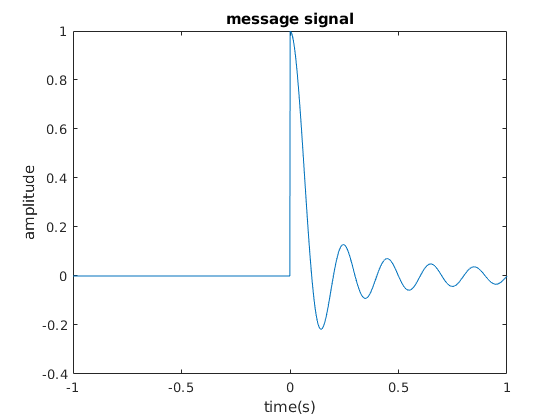

close all
fs = 600;
t_scale = 10;
v_scale = 1;
lim = 1;
causal = false;
[m ,t]= message_sinc(fs,t_scale, v_scale, lim ,causal);
%[m ,t]= message_palse(fs, lim , causal);
plot(t,m)
title('message signal');xlabel('time(s)');ylabel('amplitude');

then obtai

n message signal in frequency axis:

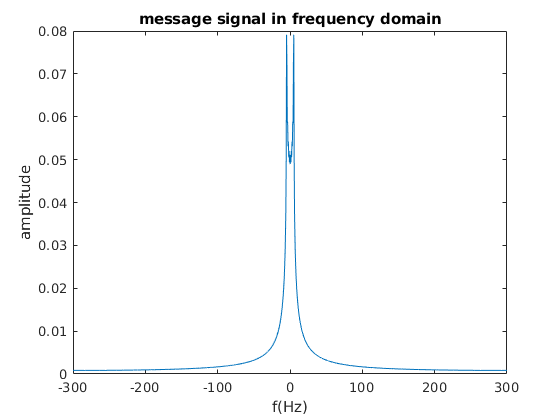

[f_m , f_axis] = ft(m, fs);
plot(f_axis , abs(f_m))
title('message signal in frequency domain');xlabel('f(Hz)');ylabel('amplitude');

why is the fourier transform diffrent from the pulse ?

what cused fourier signal to have overshoot and under-shoot on 50 Hz and -50 Hz?

how does changing fs affect overshoots ?

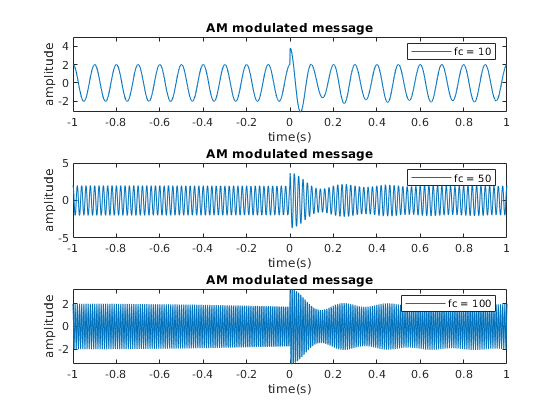

fc_1 =[10 ,50 , 100];
fc_2 = [0.25 , 600 , 1200];
ac = 2;
u = 0.9;
phase = 0;
figure;
for i=1:3
    [m_am ,t_axis]= AM_reg(m ,fs , lim , fc_1(i),ac,u , phase);
    subplot(3,1,i);
    plot(t_axis , m_am ,'DisplayName' , 'fc = '+string(fc_1(i)));
    title('AM modulated message');xlabel('time(s)');ylabel('amplitude');
    legend;
end

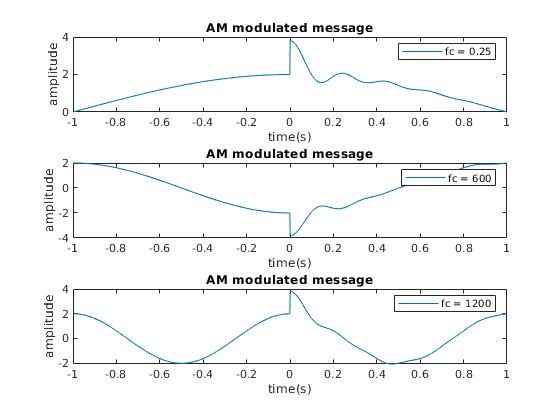

figure;
for i=1:3
    [m_am ,t_axis]= AM_reg(m ,fs , lim , fc_2(i),ac,u , phase);
    subplot(3,1,i);
    plot(t_axis , m_am ,'DisplayName' , 'fc = '+string(fc_2(i)));
    title('AM modulated message');xlabel('time(s)');ylabel('amplitude');
    legend;
end

justify plots ?

which fc is more proper for our case?

next , show modulated signal in frequency domain

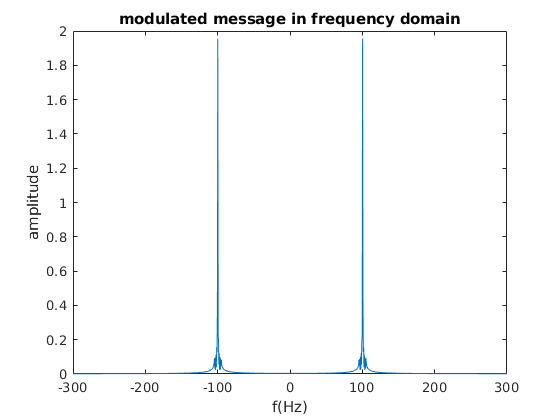

fc = 100;
[m_am ,t_axis]= AM_reg(m ,fs , lim ,fc,ac,u , phase);
[f_m_am , f_am_axis] = ft(m_am, fs);
figure;
plot(f_am_axis , abs(f_m_am))
title('modulated message in frequency domain');xlabel('f(Hz)');ylabel('amplitude');

next step is to demodulate this signal ...

[demod , a, b, t] = AM_demod(m_am , 100,fs,fc,lim,ac,u);

and plot the result

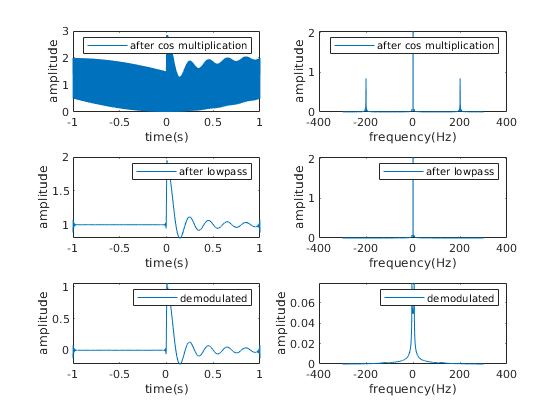

figure;
title('process of demodulation using cosine mult');
 
    subplot(3,2,1);
    plot(t, a ,'DisplayName' ,'after cos multiplication');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(a, fs);
    legend;
    subplot(3,2,2);
    plot(f_axis , abs(f) ,'DisplayName' ,'after cos multiplication');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;
    
    subplot(3,2,3);
    plot(t , b ,'DisplayName' ,'after lowpass');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(b, fs);
    legend;
    subplot(3,2,4);
    plot(f_axis , abs(f) ,'DisplayName' ,'after lowpass');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;
    
    subplot(3,2,5);
    plot(t , demod ,'DisplayName' ,'demodulated');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(demod, fs);
    legend;
    subplot(3,2,6);
    plot(f_axis , abs(f) ,'DisplayName' ,'demodulated');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;

we use mean square error as a metric for determine how our system is working

    sz = size(m_am);sz = sz(1);
    mse = sum((m- demod).^2)/sz

mse = 2.5882e-04

visualize the result

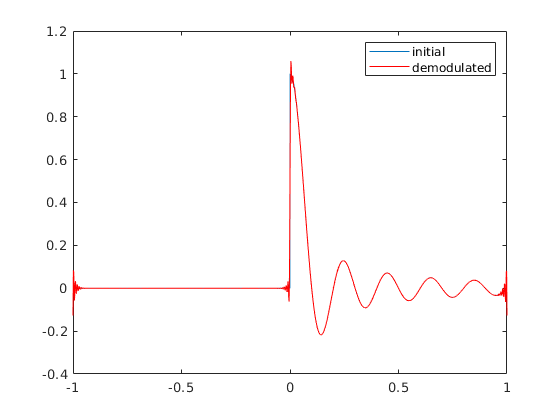

    figure;
    plot(t,m , 'DisplayName','initial');
    hold on;
    plot(t,demod,'DisplayName','demodulated','color','red');
    hold off;
    legend;

lets see how modulation index affects the accuracy of result

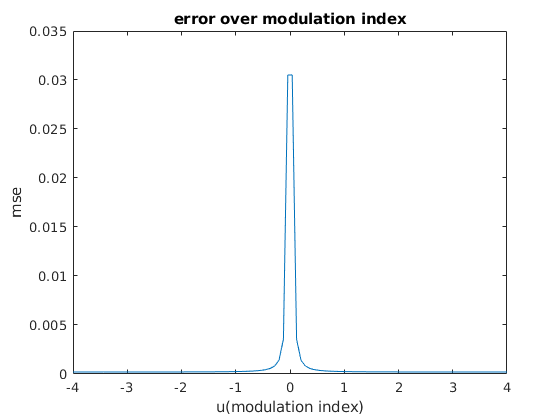

num_points = 100;
mse = zeros(num_points , 1);
u = linspace(-4 , +4 , num_points).';
for i =1:num_points
    [m_am ,t_axis]= AM_reg(m ,fs , lim ,fc,ac,u(i,1) , phase);
    [demod , a, b, t] = AM_demod(m_am , 100,fs,fc,lim,ac,u(i,1));
    sz = size(m_am);sz = sz(1);
    mse(i,1) = sum((m - demod).^2)/sz;
end

figure;
plot(u , mse);
title('error over modulation index');
xlabel('u(modulation index)');
ylabel('mse');

u = 0.9;

lets see how fc impacts our demodulation results

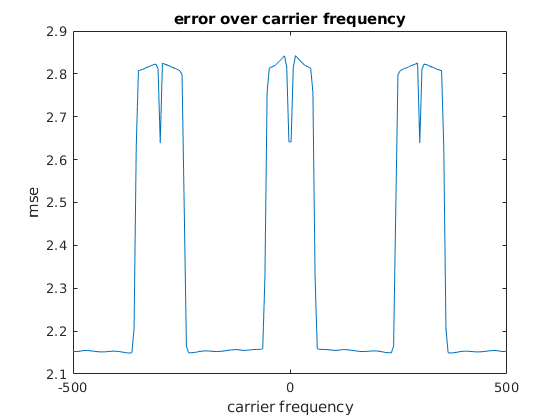

num_points = 200;
mse = zeros(num_points , 1);
fc = linspace(-500 , +500 , num_points).';
for i =1:num_points
    [m_am ,t_axis]= AM_reg(m ,fs , lim ,fc(i,1),ac,u , phase);
    [demod , a, b, t] = AM_demod(m_am , 100,fs,fc(i,1),lim,ac,u);
    sz = size(m_am);sz = sz(1);
    mse(i,1) = sum((m_am - demod).^2)/sz;
end

figure;
plot(fc , mse);
title('error over carrier frequency');
xlabel('carrier frequency');
ylabel('mse');

## DSB modulation

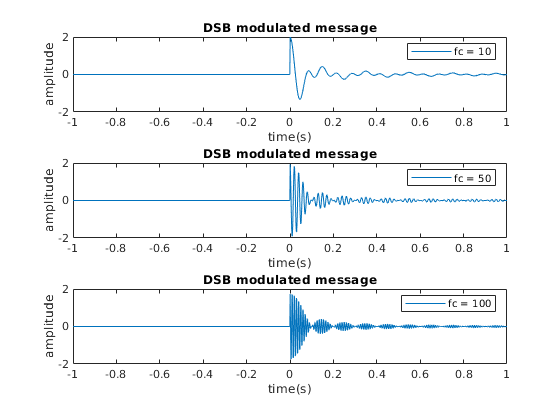

fc_1 =[10 ,50 , 100];
fc_2 = [600/4 , 600 , 1200];
ac = 2;
phase = 0;
figure;
for i=1:3
    [m_am ,t_axis]= AM_DSB(m ,fs , lim , fc_1(i),ac, phase);
    subplot(3,1,i);
    plot(t_axis , m_am ,'DisplayName' , 'fc = '+string(fc_1(i)));
    title('DSB modulated message');xlabel('time(s)');ylabel('amplitude');
    legend;
end

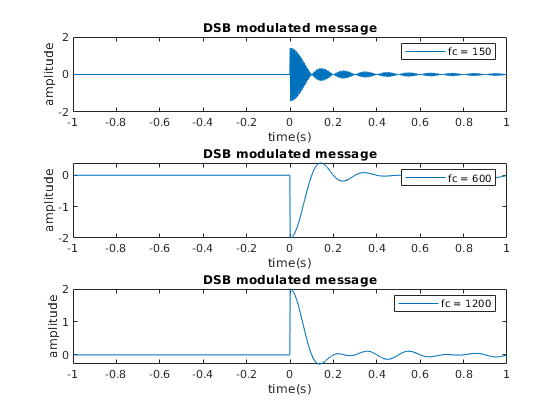

figure;
for i=1:3
    [m_am ,t_axis]= AM_DSB(m ,fs , lim , fc_2(i),ac, phase);
    subplot(3,1,i);
    plot(t_axis , m_am ,'DisplayName' , 'fc = '+string(fc_2(i)));
    title('DSB modulated message');xlabel('time(s)');ylabel('amplitude');
    legend;
end

take a look at frequency domain

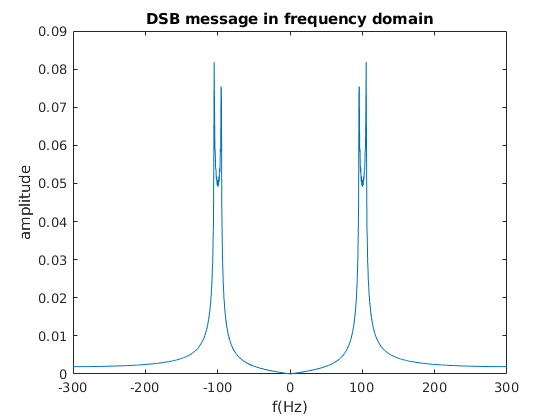

fc = 100;
[m_am ,t_axis]= AM_DSB(m ,fs , lim ,fc,ac , phase);
[f_m_am , f_am_axis] = ft(m_am, fs);
figure;
plot(f_am_axis , abs(f_m_am))
title('DSB message in frequency domain');xlabel('f(Hz)');ylabel('amplitude');

### let's implimetn DSB modulation using two conventional am modulation:

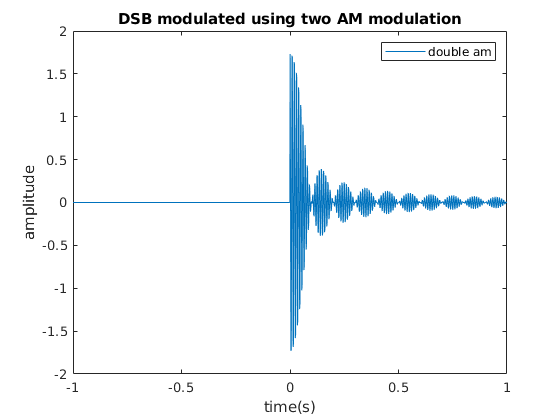

[m_dsb , t_axis] = DSB_using_AM(m , fs , lim , fc , ac , phase);

 plot(t_axis , m_dsb ,'DisplayName' , 'double am');
title('DSB modulated using two AM modulation');xlabel('time(s)');ylabel('amplitude');
legend;

[f_m_am , f_am_axis] = ft(m_am, fs);
figure;
plot(f_am_axis , abs(f_m_am))
title('DSB message in frequency domain');xlabel('f(Hz)');ylabel('amplitude');

next step is to demodulate message from DSB version

[demod , a, b, t] = DSB_demod(m_am , 100,fs,fc,lim,ac);

and plot the result

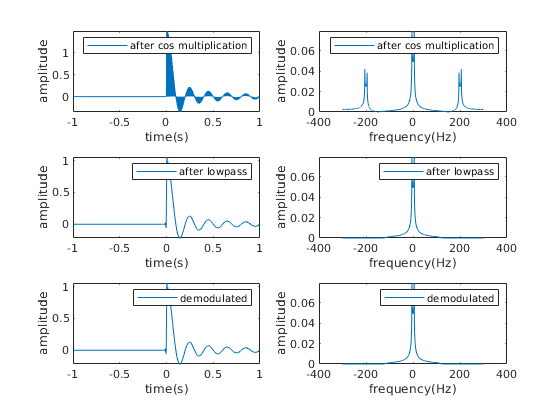

figure;
title('process of demodulation using cosine mult');
 
    subplot(3,2,1);
    plot(t, a ,'DisplayName' ,'after cos multiplication');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(a, fs);
    legend;
    subplot(3,2,2);
    plot(f_axis , abs(f) ,'DisplayName' ,'after cos multiplication');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;
    
    subplot(3,2,3);
    plot(t , b ,'DisplayName' ,'after lowpass');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(b, fs);
    legend;
    subplot(3,2,4);
    plot(f_axis , abs(f) ,'DisplayName' ,'after lowpass');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;
    
    subplot(3,2,5);
    plot(t , demod ,'DisplayName' ,'demodulated');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(demod, fs);
    legend;
    subplot(3,2,6);
    plot(f_axis , abs(f) ,'DisplayName' ,'demodulated');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;

lets see the effect of fc on mse

sz = size(m_am);sz = sz(1);
mse = sum((m - demod).^2)/sz

mse = 1.9760e-04

visualize the result

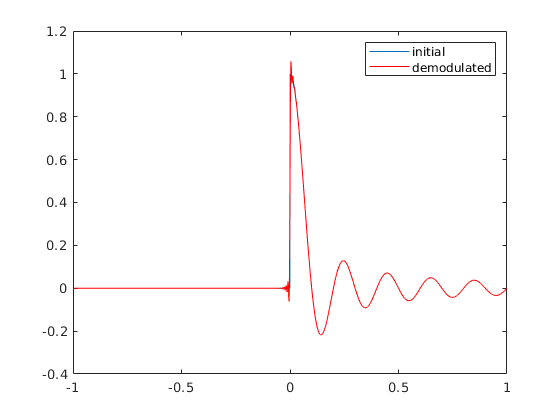

figure;
plot(t,m , 'DisplayName','initial');
hold on;
plot(t,demod,'DisplayName','demodulated','color','red');
hold off;
legend;

lets see how fc impacts our demodulation results

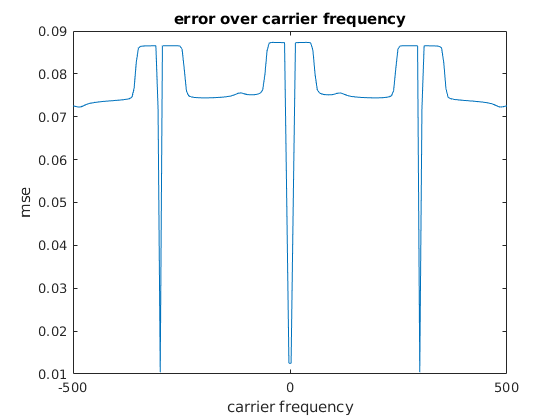

num_points = 200;
mse = zeros(num_points , 1);
fc = linspace(-500 , +500 , num_points).';
for i =1:num_points
    [m_am ,t_axis]= AM_DSB(m ,fs , lim ,fc(i,1),ac, phase);
    [demod , a, b, t] = DSB_demod(m_am , 100,fs,fc(i,1),lim,ac);
    sz = size(m_am);sz = sz(1);
    mse(i,1) = sum((m_am - demod).^2)/sz;
end

figure;
plot(fc , mse);
title('error over carrier frequency');
xlabel('carrier frequency');
ylabel('mse');

## SSB:

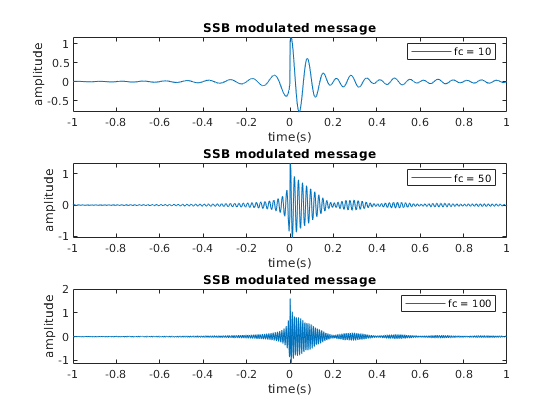

fc_1 =[10 ,50 , 100];
fc_2 = [600/4 , 600 , 1200];
ac = 2;
phase = 0;
type = true;
figure;
for i=1:3
    [m_am ,t_axis]= AM_SSB(m ,fs , lim , fc_1(i),ac, phase , type);
    subplot(3,1,i);
    plot(t_axis , m_am ,'DisplayName' , 'fc = '+string(fc_1(i)));
    title('SSB modulated message');xlabel('time(s)');ylabel('amplitude');
    legend;
end

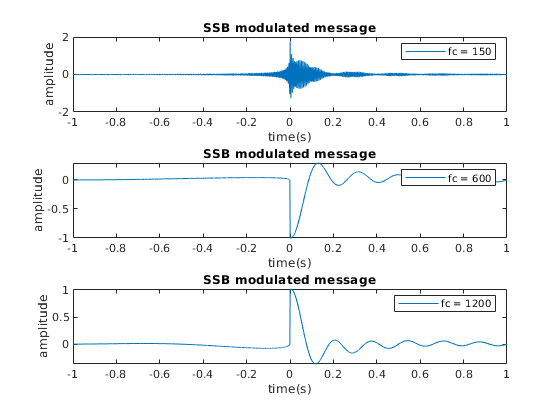

figure;
for i=1:3
    [m_am ,t_axis]= AM_SSB(m ,fs , lim , fc_2(i),ac, phase , type);
    subplot(3,1,i);
    plot(t_axis , m_am ,'DisplayName' , 'fc = '+string(fc_2(i)));
    title('SSB modulated message');xlabel('time(s)');ylabel('amplitude');
    legend;
end

take a look at frequency domain for USSB

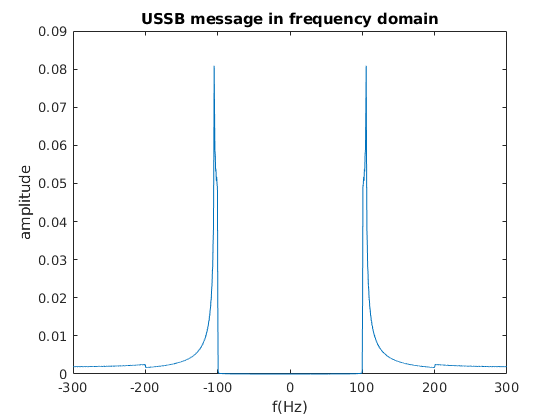

fc = 100;
type = true;
[m_am ,t_axis]= AM_SSB(m ,fs , lim ,fc,ac , phase , type);
[f_m_am , f_am_axis] = ft(m_am, fs);
figure;
plot(f_am_axis , abs(f_m_am))
title('USSB message in frequency domain');xlabel('f(Hz)');ylabel('amplitude');

take a look at frequency domain for LSSB

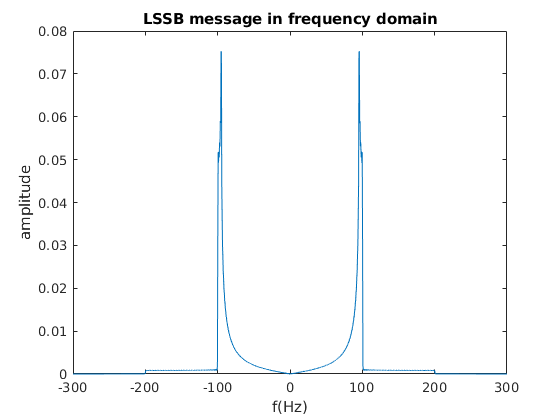

fc = 100;
type = false;
[m_am ,t_axis]= AM_SSB(m ,fs , lim ,fc,ac , phase , type);
[f_m_am , f_am_axis] = ft(m_am, fs);
figure;
plot(f_am_axis , abs(f_m_am))
title('LSSB message in frequency domain');xlabel('f(Hz)');ylabel('amplitude');

demodulation of  SSB signals using DSB product demodulator:

fc = 100;
type = true;
[m_ussb ,t_axis]= AM_SSB(m ,fs , lim ,fc,ac , phase , type);
type = false;
[m_lssb ,t_axis]= AM_SSB(m ,fs , lim ,fc,ac , phase , type);

next step is to demodulate message from SSB version

[demod_ussb , a, b, t] = SSB_demod(m_ussb , 100,fs,fc,lim,ac);

and plot the result

### USSB:

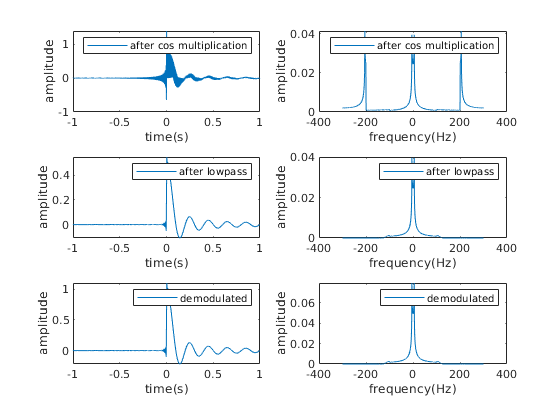

figure;
title('process of demodulation using cosine mult');
 
    subplot(3,2,1);
    plot(t, a ,'DisplayName' ,'after cos multiplication');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(a, fs);
    legend;
    subplot(3,2,2);
    plot(f_axis , abs(f) ,'DisplayName' ,'after cos multiplication');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;
    
    subplot(3,2,3);
    plot(t , b ,'DisplayName' ,'after lowpass');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(b, fs);
    legend;
    subplot(3,2,4);
    plot(f_axis , abs(f) ,'DisplayName' ,'after lowpass');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;
    
    subplot(3,2,5);
    plot(t , demod_ussb ,'DisplayName' ,'demodulated');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(demod_ussb, fs);
    legend;
    subplot(3,2,6);
    plot(f_axis , abs(f) ,'DisplayName' ,'demodulated');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;

### LSSB:

[demod_lssb , a, b, t] = SSB_demod(m_lssb , 100,fs,fc,lim,ac);

and plot the result

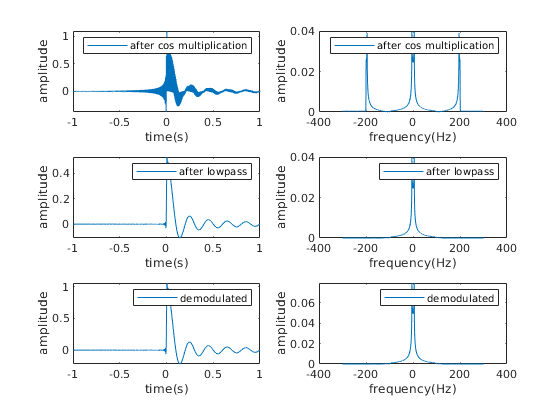

figure;
title('process of demodulation using cosine mult');
 
    subplot(3,2,1);
    plot(t, a ,'DisplayName' ,'after cos multiplication');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(a, fs);
    legend;
    subplot(3,2,2);
    plot(f_axis , abs(f) ,'DisplayName' ,'after cos multiplication');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;
    
    subplot(3,2,3);
    plot(t , b ,'DisplayName' ,'after lowpass');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(b, fs);
    legend;
    subplot(3,2,4);
    plot(f_axis , abs(f) ,'DisplayName' ,'after lowpass');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;
    
    subplot(3,2,5);
    plot(t , demod_lssb ,'DisplayName' ,'demodulated');
    xlabel('time(s)');ylabel('amplitude');
    [f , f_axis] = ft(demod_lssb, fs);
    legend;
    subplot(3,2,6);
    plot(f_axis , abs(f) ,'DisplayName' ,'demodulated');
    xlabel('frequency(Hz)');ylabel('amplitude');
    legend;

compare mse of two methods :

sz = size(m);sz = sz(1);
mse_ussb = sum((m - demod_ussb).^2)/sz

mse_ussb = 1.8547e-04

mse_lssb = sum((m - demod_lssb).^2)/sz

mse_lssb = 2.6126e-04

visualize the result

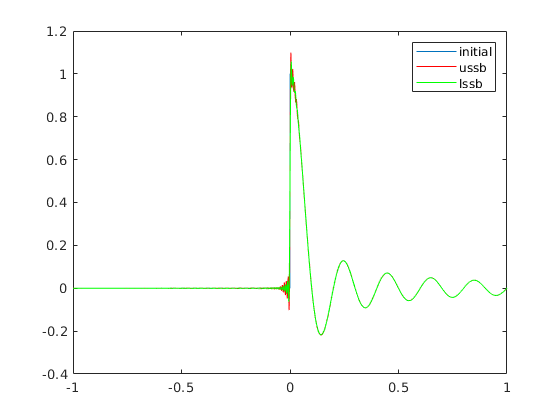

figure;
plot(t,m , 'DisplayName','initial');
hold on;
plot(t,demod_ussb,'DisplayName','ussb','color','red');
plot(t,demod_lssb,'DisplayName','lssb','color','green');
hold off;
legend;

## error in carrier frequency and its impact on demodulated message

###   convensional AM:

fc = 100;
f0 = fc/100;
u = 0.9;
[m_am ,t_axis]= AM_reg(m ,fs , lim ,fc,ac,u , phase);
[demod , a, b, t] = AM_demod(m_am , 100,fs,fc-f0,lim,ac,u);

sz = size(m_am);sz = sz(1);
mse = sum((m- demod).^2)/sz

mse = 1.8527

visualize the result

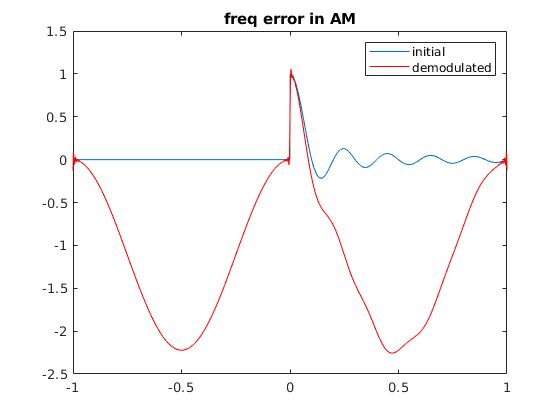

    figure;
    plot(t,m , 'DisplayName','initial');
    hold on;
    plot(t,demod,'DisplayName','demodulated','color','red');
    title("freq error in AM");
    hold off;
    legend;

mse over fc

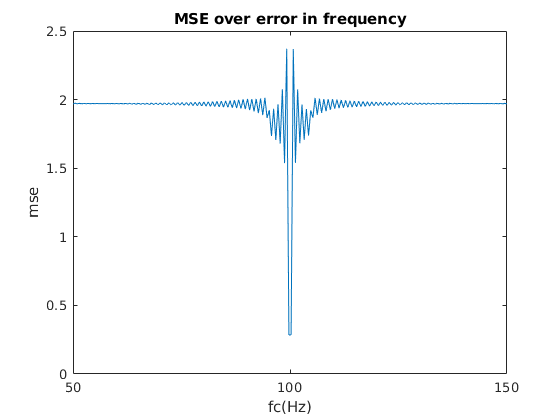

num_pints = 200;
f0 = linspace(- fc/2 ,fc/2 , num_points).';
mse = zeros(num_points , 1);sz = size(m_am);sz = sz(1);
for i = 1:num_points
    [demod , a, b, t] = AM_demod(m_am , 100,fs,fc+f0(i,1),lim,ac,u);
    mse(i,1) = sum((m- demod).^2)/sz;
end
figure;
plot(fc-f0 , mse);
title('MSE over error in frequency');xlabel('fc(Hz)');ylabel('mse');

### DSB:

fc = 100;
f0 = fc/100;
[m_am ,t_axis]= AM_DSB(m ,fs , lim ,fc,ac , phase);
[demod , a, b, t] = DSB_demod(m_am , 100,fs,fc-f0,lim,ac);

sz = size(m_am);sz = sz(1);
mse = sum((m- demod).^2)/sz

mse = 0.0023

visualize the result

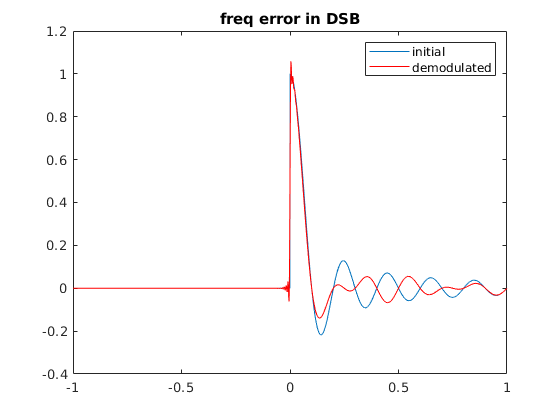

figure;
plot(t,m , 'DisplayName','initial');
hold on;
plot(t,demod,'DisplayName','demodulated','color','red');
title("freq error in DSB");
hold off;
legend;

mse over fc

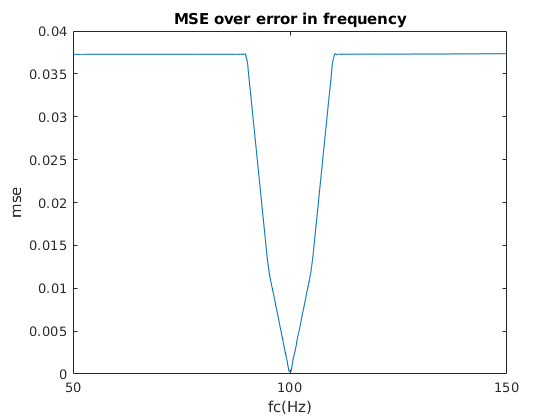

num_pints = 20;
f0 = linspace(- fc/2 ,fc/2 , num_points).';
mse = zeros(num_points , 1);sz = size(m_am);sz = sz(1);
for i = 1:num_points
    [demod , a, b, t] = DSB_demod(m_am , 100,fs,fc+f0(i,1),lim,ac);
    mse(i,1) = sum((m- demod).^2)/sz;
end
figure;
plot(fc-f0 , mse);
title('MSE over error in frequency');xlabel('fc(Hz)');ylabel('mse');

### USSB:

fc = 100;
f0 = fc/100;
type = true;
[m_am ,t_axis]= AM_SSB(m ,fs , lim ,fc,ac , phase , type);
[demod_ussb , a, b, t] = SSB_demod(m_ussb , 100,fs,fc,lim,ac);

sz = size(m_am);sz = sz(1);
mse = sum((m- demod).^2)/sz

mse = 0.0452

visulize the result

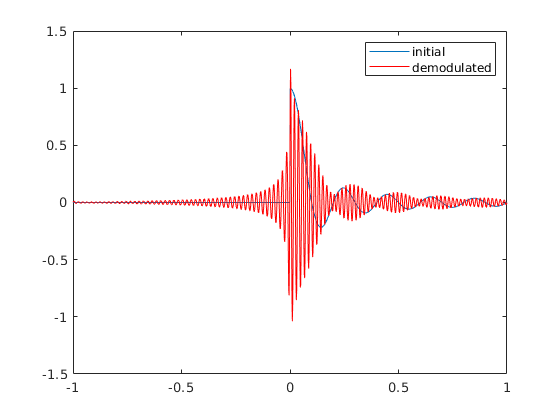

figure;
plot(t,m , 'DisplayName','initial');
hold on;
plot(t,demod,'DisplayName','demodulated','color','red');
hold off;
legend;

mse over fc

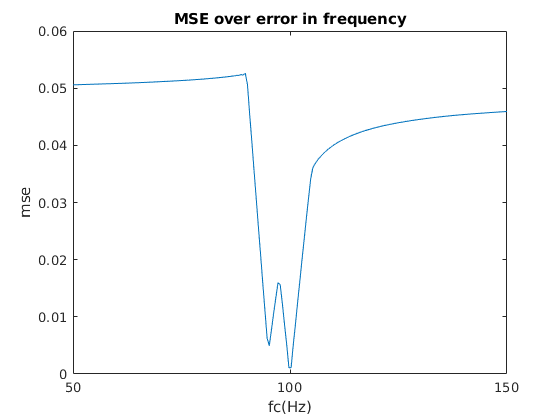

num_pints = 200;
f0 = linspace(- fc/2 ,fc/2 , num_points).';
mse = zeros(num_points , 1);sz = size(m_am);sz = sz(1);
for i = 1:num_points
    [demod , a, b, t] = SSB_demod(m_am , 100,fs,fc+f0(i,1),lim,ac);
    mse(i,1) = sum((m- demod).^2)/sz;
end
figure;
plot(fc-f0 , mse);
title('MSE over error in frequency');xlabel('fc(Hz)');ylabel('mse');

### LSSB:

fc = 100;
f0 = fc/100;
type = false;
[m_am ,t_axis]= AM_SSB(m ,fs , lim ,fc,ac , phase , type);
[demod_ussb , a, b, t] = SSB_demod(m_ussb , 100,fs,fc,lim,ac);

sz = size(m_am);sz = sz(1);
mse = sum((m- demod).^2)/sz

mse = 0.0506

visulize the result

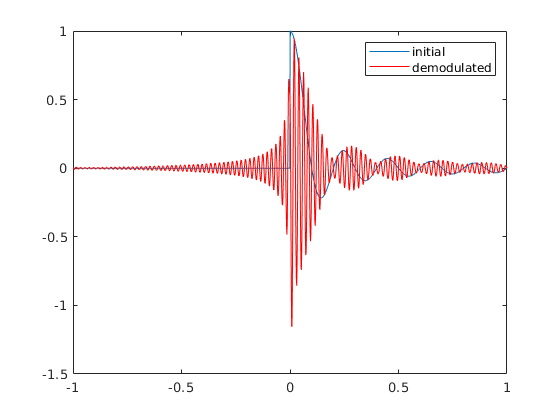

figure;
plot(t,m , 'DisplayName','initial');
hold on;
plot(t,demod,'DisplayName','demodulated','color','red');
hold off;
legend;

mse over fc

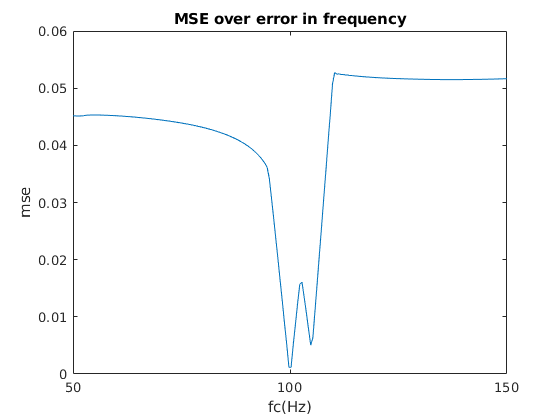

num_pints = 20;
f0 = linspace(- fc/2 ,fc/2 , num_points).';
mse = zeros(num_points , 1);sz = size(m_am);sz = sz(1);
for i = 1:num_points
    [demod , a, b, t] = SSB_demod(m_am , 100,fs,fc+f0(i,1),lim,ac);
    mse(i,1) = sum((m- demod).^2)/sz;
end
figure;
plot(fc-f0 , mse);
title('MSE over error in frequency');xlabel('fc(Hz)');ylabel('mse');